## Load Data

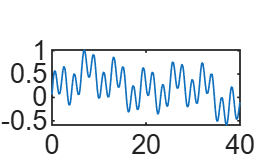

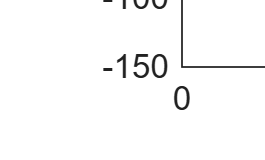

% Sinusoid data
load('Isolated_Flywheel_action.mat')

y = angular_velocity.data;
u_current = dc_current.data;
u = stim_input_1;
%u = u_current;
N = size(t,2);
end_train = floor(N*1/2);
%{
y = y(1:end_train);
t = t(1:end_train);
N = size(t,2);
%}
figure; 
plot(t,u)
y = y(3:end);
u = u(3:end);
N = N-2;
t = t(3:end);
clearvars -except y N t u

## Apply PEM

theta0 = [-5 1000 0.2]';
theta = theta0;
lambda = 0.1;
maxiter = 10000;
p = 3;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    [Abar,Bbar, C,x0] = theta2matrices(theta, h);
    [yhat, xhat] = simsystem_y_as_vec(Abar, Bbar, C, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h, u);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

[yhat, xhat] = simsystem_y_as_vec(Abar, Bbar, C, x0, u);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');